# **Implementing a novel gain stage to the filter**

## **Idea**

The Moog LPF, like other LPFs, attenuates the high-frequency content of the incoming signal in[n] beyond the passband & outputs y[n].

However, the signal energy is removed, thus reducing the overall signal amplitude in time domain.

This project aims to implement an additional gain stage (per suggested by Daly) to the filter that 'makes up' the gain & restores signal energy.

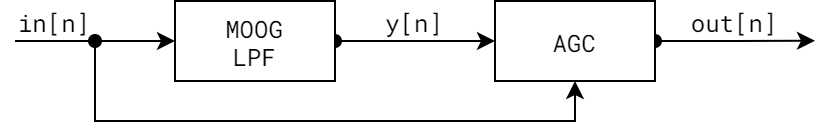

Original paper by Huovilainen [here](https://cpb-us-w2.wpmucdn.com/sites.gatech.edu/dist/e/466/files/2016/11/P_061.pdf). Original GitHub source code in C++ [here](https://github.com/ddiakopoulos/MoogLadders).

Code derived from equations per analyis by Paul Daly - see thesis [here](http://www.acoustics.ed.ac.uk/wp-content/uploads/AMT_MSc_FinalProjects/2012__Daly__AMT_MSc_FinalProject_MoogVCF.pdf).

# Preparations

close all; clear; clc;

Loads audio file of specific frequency - uses square waves for testing.

% Sets sampling frqc to audio output (44.1k Hz)
Fs = 44.1e+3;
Ts = 1/Fs;
duration = 1;
t = (0:Ts:duration);
% duration = duration + 0.1;
% in_audio = (t == 0.1);
in_audio = zeros(length(t)-1, 1)

in_audio =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


in_audio(1, :) = 1;

Plots the input audio into the time domain

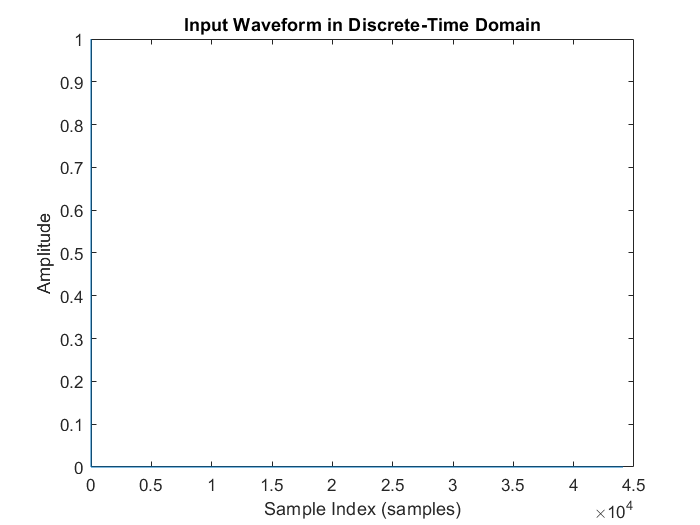

plot(in_audio);
title("Input Waveform in Discrete-Time Domain");
xlabel("Sample Index (samples)");
ylabel("Amplitude");

Before plotting numerical results we need to define the range to use for plots.

Recall the formula for sampling & frequency normalisation.


$$\Omega = 2\pi f T_s \equiv 2\pi \frac{f}{f_s} = 2\pi F$$


We defined the range of frequency to be 1:Fs. This obtains the normalised angular frequency for 0:2pi.

% NOTE: Define normalised frequency HERE
range_f = (1 : Fs/2);
% Recall that sampling results in identical peaks
% So half since we want range of 0:pi & not 0:2pi
% So given cycles/second this ranges 0:1
range_f_normalised = range_f * (2 * pi) / Fs;

Let us plot the FFT of the impulse as well.

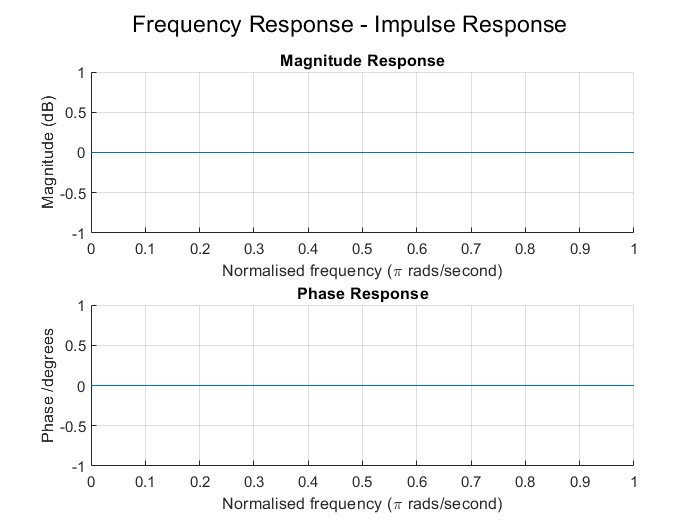

f_plotFrqcResp(in_audio, range_f, Fs, "Frequency Response - Impulse Response", true, false, false);

As an impulse, we expect a full range of frequency with magnitude 1.

Note: dB axis might not be as useful here since doing so results in "Magnitude (dB)" of 0 instead of 1 (as expected)

# Linear Moog VCF model

The transfer function, thus frequency response, of the analog Moog VCF was determined by Smith and Stilton as


$$H(s)=\frac{1}{k + \left(1 + \frac{s}{\omega_c}\right)^4}
\equiv
\left(
\frac{1}{k+
\left(\frac{1}{\omega_c^4}s^4 + \frac{4}{\omega_c^3}s^3 + \frac{6}{\omega_c^2}s^2 + \frac{4}{\omega_c}s + 1 \right)} 
\right)
\equiv
H(j\omega)=\frac{1}{k + \left(1 + \frac{j\omega}{\omega_c}\right)^4} $$


where $s=\sigma + j\omega = j2\pi f$.

The frequency responses of the model can thus be modelled for the Laplace domain.

gainFeedbk = 3.99; % Feedback gain
Fc = 100; % Cutoff frequency
Fc = 440;

We can plot the frequency response of the analogue linear model.

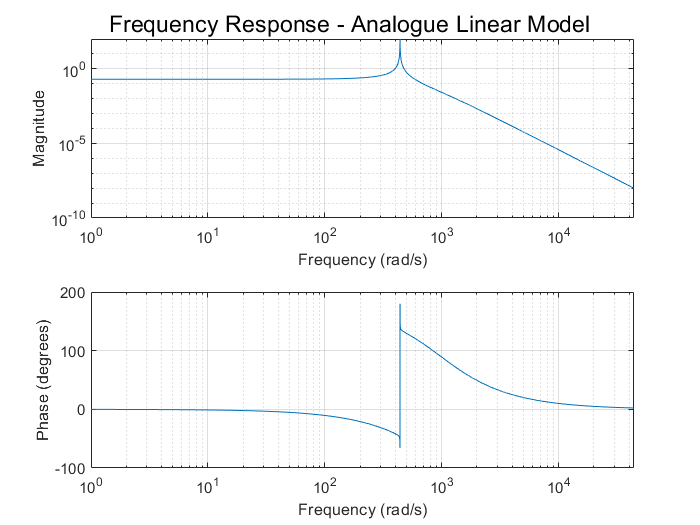

Wc = Fc;
H_num = 1;
H_den = [   (1/(Wc ^ 4)) ...
            (4/(Wc ^ 3)) ...
            (6/(Wc ^ 2)) ...
            (4/(Wc ^ 1)) ...
            (1 + gainFeedbk) ...
            ];
figure;
sgtitle("Frequency Response - Analogue Linear Model")
freqs(H_num, H_den, (1:Fs))

Let us plot the frequencies in order.

Wc = Fc;
range_gainFeedbk = [0, 2, 3.99];
ss_data_magnt = [];
ss_data_phase = [];
H_num = 1;
for i_frqc = 0:1
    wc_now = 100 * (100 ^ i_frqc);
    for i_gainFeedbk = 1:length(range_gainFeedbk)
        H_den = [   (1/(wc_now ^ 4)) ...
                    (4/(wc_now ^ 3)) ...
                    (6/(wc_now ^ 2)) ...
                    (4/(wc_now ^ 1)) ...
                    (1 + range_gainFeedbk(i_gainFeedbk)) ...
                    ];
        h_now = freqs(H_num, H_den, (1:Fs));
        ss_data_magnt(i_frqc+1, i_gainFeedbk, :) = abs(h_now(range_f));
        ss_data_phase(i_frqc+1, i_gainFeedbk, :) = angle(h_now(range_f));
    end
end

Now that we have generated the data, let us plot the magnitude response.

arr_plot_magnt = [];
range_color = ['g', 'b', 'r'];
figure;
sgtitle("Frequency response of analogue linear Moog VCF model (varying \omega_c and k)", 'FontSize', 12)
subplot(2, 1, 1);
subtitle("Magnitude response")
ylim([-60, inf])
set(gca, 'XScale', 'log');
xlim([0, Fs/2])
xlabel("Frequency \omega_c (rads^{-1})")
ylabel("Magnitude (dB)")
grid on
hold on
for i_gainFeedbk = 1:length(range_gainFeedbk)
    for i_frqc = 1:2
        data_now = reshape(ss_data_magnt(i_frqc, i_gainFeedbk, :), [Fs/2, 1, 1]);
        arr_plot_magnt(end+1) = plot(range_f, 10*log(data_now), 'color', range_color(i_gainFeedbk));
    end
end
legend(arr_plot_magnt([1, 3, 5]), {'k=0','k=2','k=3.99'}, 'Location', 'northwest')

On the same plot (second subplot) let us plot the phase responses as well.

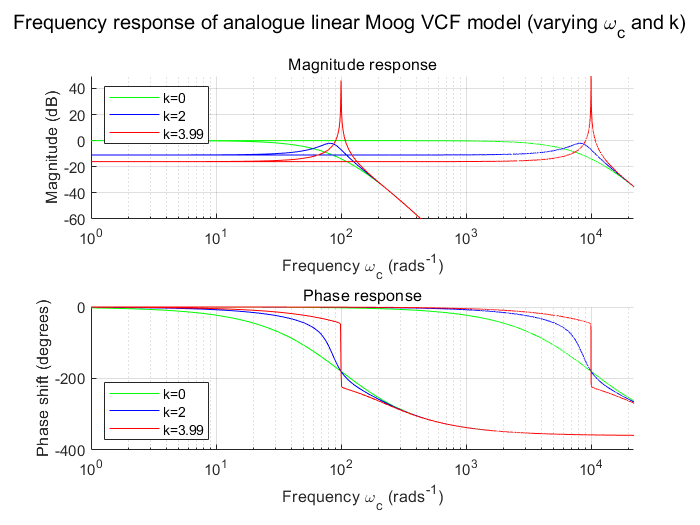

arr_plot_phase = [];
subplot(2, 1, 2);
subtitle("Phase response")
ylim([-400, 0])
set(gca, 'XScale', 'log');
xlim([0, Fs/2])
xlabel("Frequency \omega_c (rads^{-1})")
ylabel("Phase shift (degrees)")
grid on
hold on
for i_gainFeedbk = 1:length(range_gainFeedbk)
    for i_frqc = 1:2
        data_now = reshape([ss_data_phase(i_frqc, i_gainFeedbk, :)  * 180 / pi], [Fs/2, 1, 1]);
        arr_plot_phase(end+1) = plot(range_f, mod(data_now, 360)-360, 'color', range_color(i_gainFeedbk));
    end
end
legend(arr_plot_phase([1, 3, 5]), {'k=0','k=2','k=3.99'}, 'Location', 'southwest')

Let us also plot the PZ diagram by varying the feedback gain.

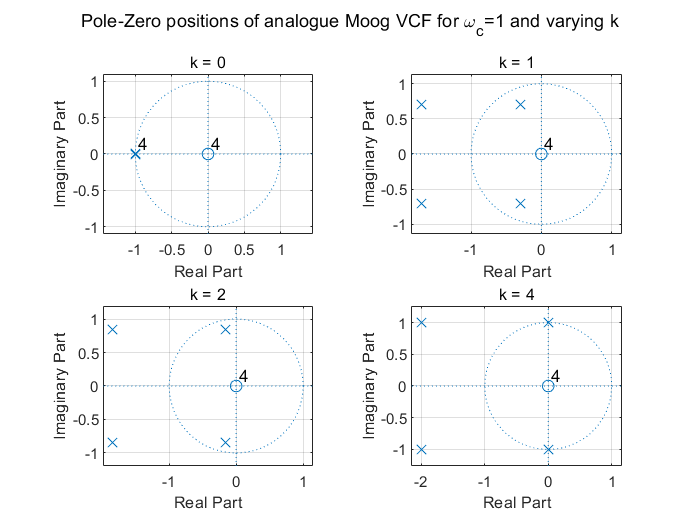

range_gainFeedbk = [0, 1, 2, 4];
H_num = 1;

wc_now = 1; %100 * (100 ^ i_frqc);
plot_pz = [];
for i_gainFeedbk = 1:length(range_gainFeedbk)
    H_den = [ (1/(wc_now ^ 4)) ...
                        (4/(wc_now ^ 3)) ...
                        (6/(wc_now ^ 2)) ...
                        (4/(wc_now ^ 1)) ...
                        (1 + range_gainFeedbk(i_gainFeedbk)) ...
                        ];
    plot_pz(end+1, :) = H_den;
end
figure;
title("Pole-Zero positions of analogue Moog VCF", 'FontSize', 12)
subplot(2, 2, 1);
zplane(H_num, plot_pz(1, :));
subtitle("k = 0") 
grid on
subplot(2, 2, 2);
zplane(H_num, plot_pz(2, :));
subtitle("k = 1") 
grid on
subplot(2, 2, 3);
zplane(H_num, plot_pz(3, :));
subtitle("k = 2") 
grid on
subplot(2, 2, 4);
zplane(H_num, plot_pz(4, :));
subtitle("k = 4") 
grid on
sgtitle("Pole-Zero positions of analogue Moog VCF for \omega_c=1 and varying k", 'FontSize', 11)

$H(s)$ was calculated for each integer $f$ (where $f \in [0, 22050]$).

The magnitude response of the analog filter was determined by plotting $20log_{10}|H(s)|$ across the range of $f$ - note the full-scale decibel used.

The phase angles $\angle H(s)$ was also plotted against $f$ to calculate the phase response, in this case in degrees.

# Huovilainen's Linear Models

## Unit-Delay Implementation

Huovilainen's "unit delay" implementation uses Euler's method, its iterations are defined per following, where $g=1-e^{-\omega_{c, a}/F_s}$ is the weighing coefficient, such that $\omega_{c,analog} = \frac{2}{T_s}tan\left(T_s\frac{\omega_{c,d}}{2}\right)$ is the "analog" cut-off frequency, and $\omega_{c,d}$ is the "digital" cut-off frequency set by the user.


$$y_{a}[n] = y_{a}[n-1] + g\left(x[n] - y_{a}[n-1] - ky_{d}[n-1]\right)$$



$$y_{b}[n] = y_{b}[n-1] + g\left(y_{a}[n] - y_{b}[n-1]\right)$$



$$y_{c}[n] = y_{c}[n-1] + g\left(y_{b}[n] - y_{c}[n-1]\right)$$



$$y_{d}[n] = y_{d}[n-1] + g\left(y_{c}[n] - y_{d}[n-1]\right)$$


The model can therefore be represented by the following IIR filter

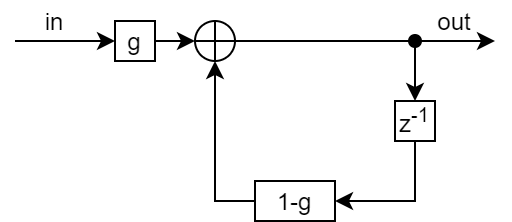

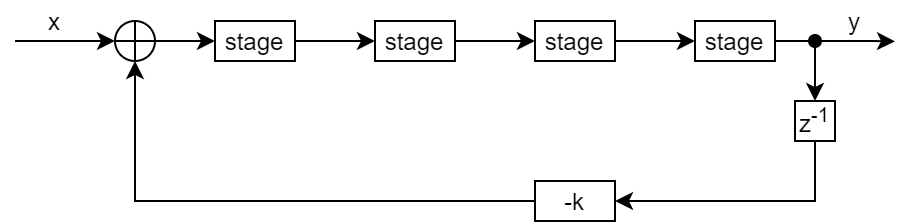

We can find the frequency response in the z-domain.


$$V_o[n] = V_o[n-1] + g( V_i[n]  - V_o[n-1])$$



$$V_o[n] = (1-g)V_o[n-1]+gV_i[n]$$



$$V_o(z)=(1-g)V_o(z)z^{-1}+gV_i(z)$$



$$H(z) :=
\frac{V_o(z)}{V_i(z)}
=
\frac{g}{1+z^{-1}(g-1)}
\equiv
\frac{1}{\left(\frac{1}{g}\right) + z^{-1} \left( 1 - \frac{1}{g} \right) }$$



$$H(z = e^{j\omega})
=
\frac{1}
{\left(\frac{1}{g}\right)
+
e^{-j\omega}{\left(1-\frac{1}{g}\right)
}$$



$$H_{s4}(z)=\frac{g^4}{(1+z^{-1}(g-1))^4}$$



$$H_{all}(z) = \frac{H_{s4}}{1+z^{-1}kH_{s4}}
\equiv
\frac{H_{s4}/k}{\frac{1}{k}+z^{-1}H_{s4}}$$


coefWeight = f_coefWeight(Fc, Fs);

Given the gain coefficient, we can plot the frequency response for each stage.

### Analytical Results

To obtain analytical results from the transfer function in MATLAB, we define the symbolic variable.

% Defining transfer function in z-domain
z = tf('z', -1);

Here, we can define the transfer functions for all the stages.

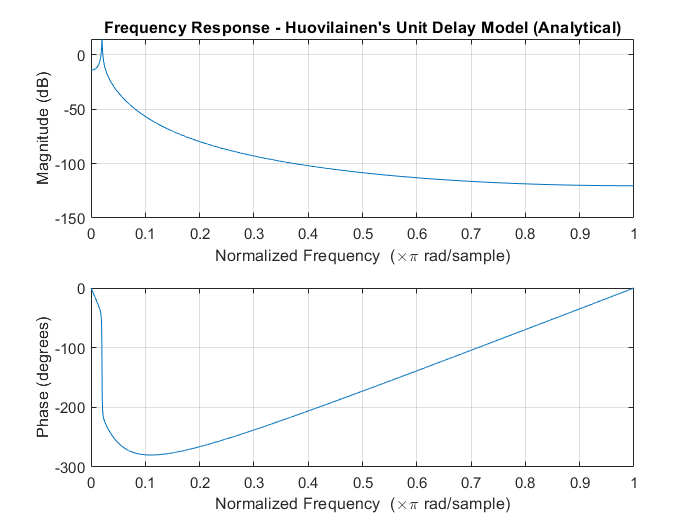

tf_1 = (coefWeight)/(1 + (z^-1 * (coefWeight - 1)));
tf_4 = tf_1 ^ 4;
tf_full_unit = (tf_4)/(1 + (z^-1 * gainFeedbk * tf_4));
[num_full_unit, den_full_unit] = tfdata(tf_full_unit);
[num_full_unit, den_full_unit] = deal(cell2mat(num_full_unit), cell2mat(den_full_unit));
figure;
freqz(num_full_unit, den_full_unit, Fs)
title("Frequency Response - Huovilainen's Unit Delay Model (Analytical)")

To find the pole placements & root loci on the z-plane, we can plot the transfer functions.

Note that in the report, this diagram MUST be cleaned up!

We can determine that the responses in frequency & z domains are identical. Note the normalised frequency range on the latter extending to pi - this is because the pi-2pi is a mirrored identical of the responses from 0-pi due to aliasing at Fs/2.

### Numerical Results

We can plot the numerical results of the unit-delay model.

in_audio = in_audio(:, 1);
duration = length(in_audio)/Fs;
t = (0:1/Fs:duration);
tic;
out_linear_unit = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "linear_unit");
toc;

Elapsed time is 0.031490 seconds.


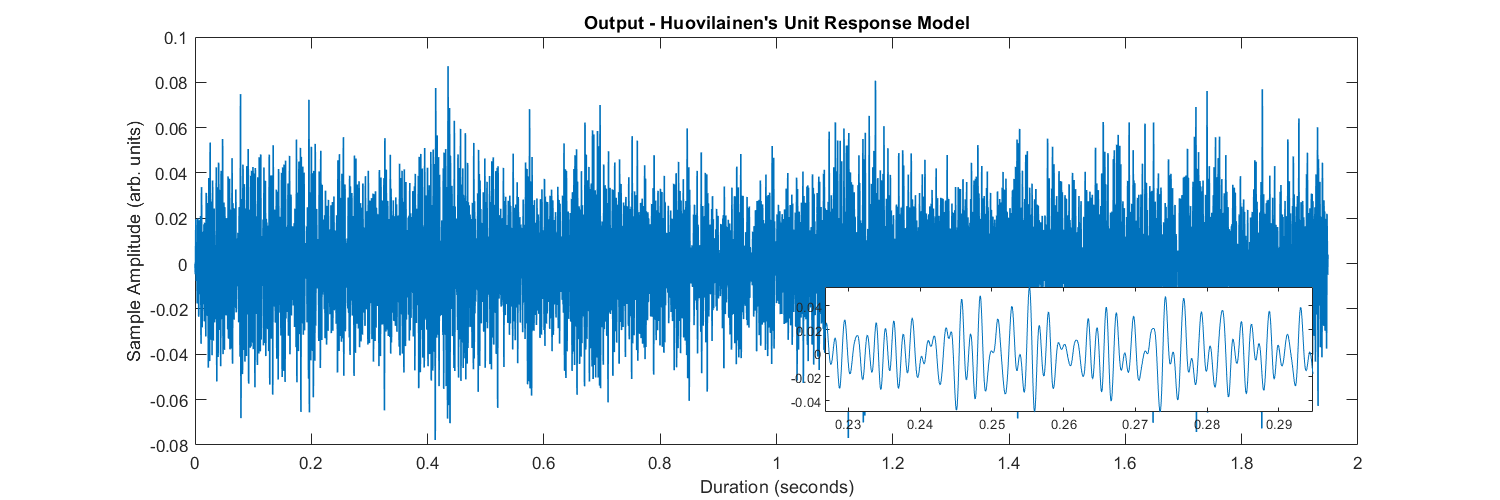

figure;
plot(t(1:end-1), out_linear_unit, 'LineWidth', 1);
title("Output - Huovilainen's Unit Response Model");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.175 0.325 0.25])
box on % put box around new pair of axes
plot(t(10000:13000), out_linear_unit(10000:13000)) % plot on new axes
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

We can now plot the numerical results.

NOTE: To view spectrum in normalized frequency, uncomment the lines.

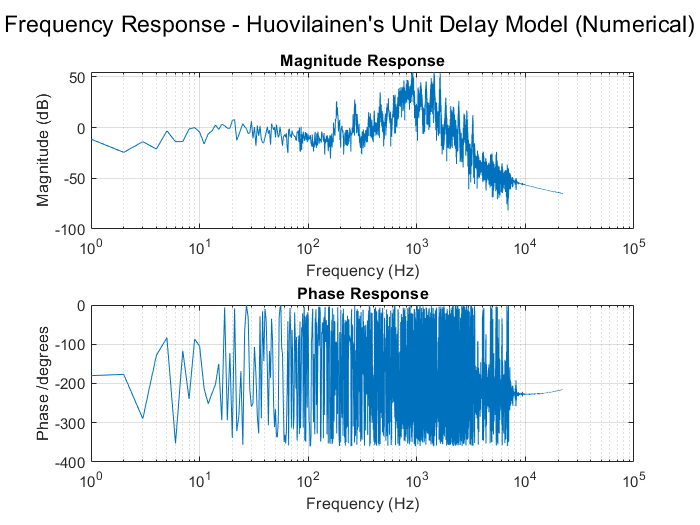

f_plotFrqcResp(out_linear_unit, range_f, Fs, "Frequency Response - Huovilainen's Unit Delay Model (Numerical)", false, true, false);

Note the subscripts $[a,b,c,d]$ refer to the first, second, third, and fourth stages of the ladder (rising from the bottom).

Also note $x_n$ is the input sequence.

The calculations must be carried out in that specific order.

The input signal $x$ is a pulse train of $N=10^{14}$ samples (albeit varying given the sampling frequency).

The recursive relations are used in a loop of $N$ iterations, where each iteration stores the output $y_d$ being the filter impluse response.

The magnitude response was calculated in dBFS as $20log_10|FFT(y_d)|$, where $FFT$ is the fast Fourier transform function.

The phase angles of $y_d$ were extracted to calculate the phase response.

The magnitude & phase responses were plotted against the frequency bins of the $FFT$ where the $n^{th}$ bin equals $F_s n / N$ for $n \in [0, (N-1)]$. $N$ was chosen to be large to increase the $FFT$ resolution, and thus the plot.

## Unit-and-a-Half Delay Implementation

The "unit-and-a-half" delay is similar to the original "unit-delay" model & simply changes the first iteration.


$$y_{a}[n] = y_{a}[n-1] + g\left(x[n] - k\frac{y_{d}[n-1] + y_{d}[n-2]}{2} - y_{a}[n-1]\right)$$


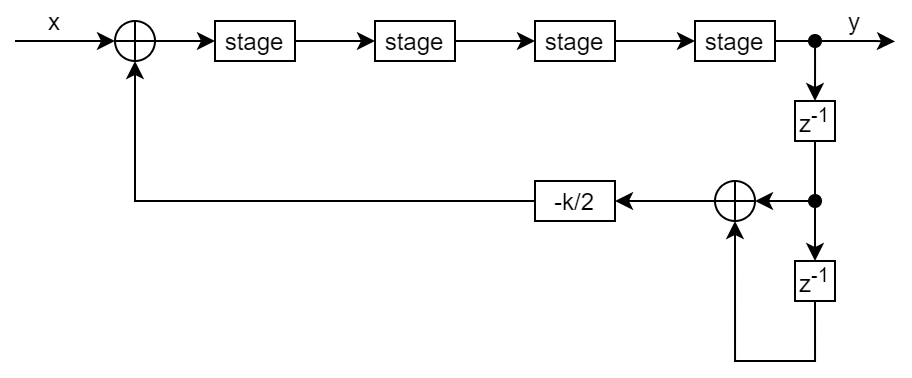


$$H_{all}(z) = \frac{H_{s4}}{1+\left(\frac{k}{2}\right)H_{s4}(z^{-1}+z^{-2})}$$


### Analytical Results

To obtain analytical results from the transfer function in MATLAB, we use the symbolic variable from the unit delay response model.

Here, we can define the transfer functions for all the stages. Since we've defined them before, the same transfer function given single stage can be used.

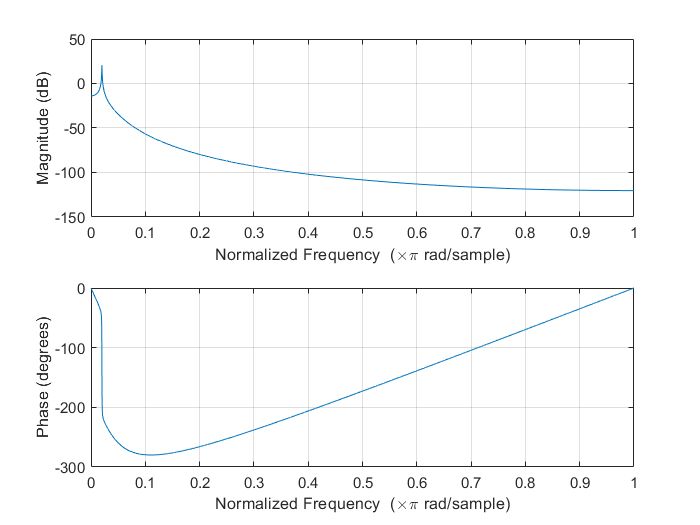


tf_full_half = (tf_4)/(1 + ((z^-1 + z^-2) * 0.5 * gainFeedbk * tf_4));
[num_full_half, den_full_half] = tfdata(tf_full_half);
[num_full_half, den_full_half] = deal(cell2mat(num_full_half), cell2mat(den_full_half));
figure;
sgtitle("Frequency Response - Huovilainen's 'Unit-and-a-Half' Delay Model (Analytical)")
freqz(num_full_half, den_full_half, Fs)

To find the pole placements & root loci on the z-plane, we can plot the transfer functions.

### Numerical Results

tic;
out_linear_half = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "linear_half");
toc;

Elapsed time is 0.037133 seconds.


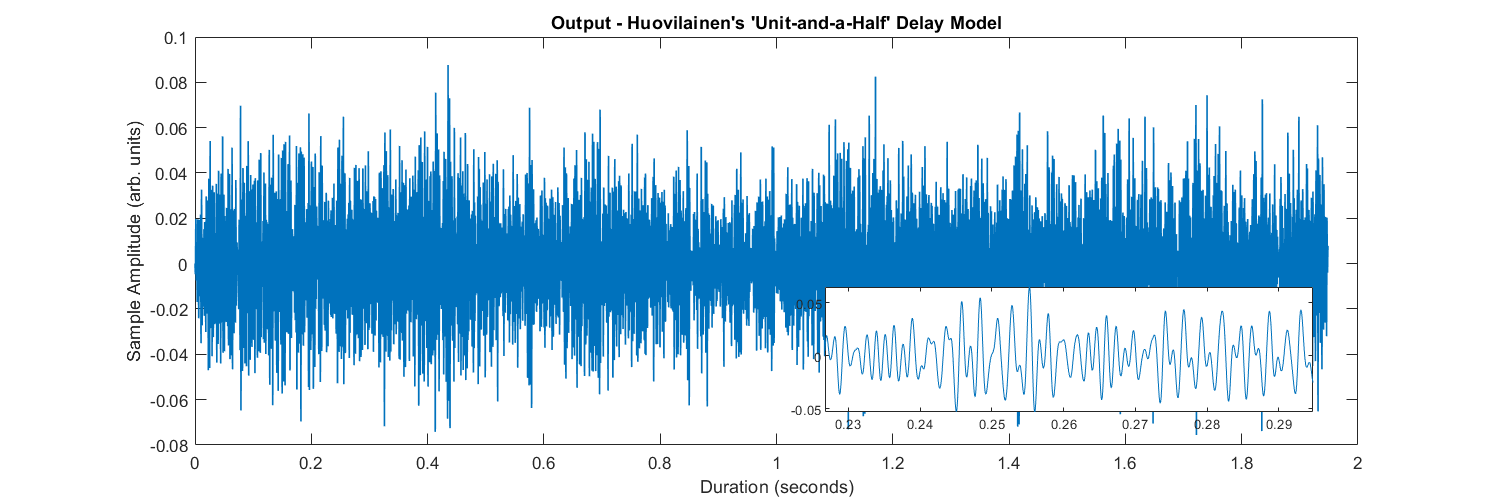

figure;
plot(t(1:end-1), out_linear_half, 'LineWidth', 1);
title("Output - Huovilainen's 'Unit-and-a-Half' Delay Model");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.175 0.325 0.25])
box on % put box around new pair of axes
plot(t(10000:13000), out_linear_half(10000:13000)) % plot on new axes
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

Let us plot the frequency response.

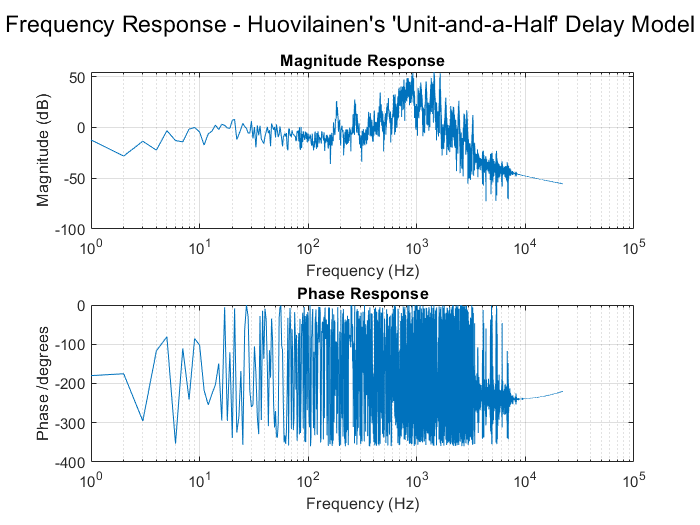

f_plotFrqcResp(out_linear_half, range_f, Fs, "Frequency Response - Huovilainen's 'Unit-and-a-Half' Delay Model", false, true, false);

Notice the phase distortions in the output signal. This was noted in Daly's thesis.

### Tuned Unit-and-a-Half Delay Implementation

Huovilainen also used a tuning table to tune the user input to a specific frequency, such that it eliminates any remaining errors in the frequency response. These are implemented via an interpolating function, see the paper in the link.

Note that the values are only functional when $F_s = 88.2k Hz$.

Note Huovilainen states that no additional filter-tuning is required as his filter is based on the analog circuit alone.

# Huovilainen's Non-linear Model

Huovilainen's linear models presented above can be transformed to a non-linear variant.


$$y_{a}[n] = y_{a}[n-1] + g\left(tanh\left(x[n] - k\frac{y_{d}[n-1] + y_{d}[n-2]}{2}\right) - tanh(y_{a}[n-1])\right)$$



$$y_{b}[n] = y_{b}[n-1] + g\left(tanh(y_{a}[n]) - tanh(y_{b}[n-1])\right)$$



$$y_{c}[n] = y_{c}[n-1] + g\left(tanh(y_{b}[n]) - tanh(y_{c}[n-1])\right)$$



$$y_{d}[n] = y_{d}[n-1] + g\left(tanh(y_{c}[n]) - tanh(y_{d}[n-1])\right)$$


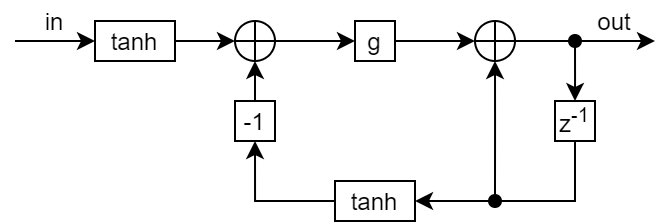

Single stage of nonlinear

The overarching 'super-stage' is the same as the unit-and-a-half delay model.

### Numerical Results

figure;
tic;
out_nonlinear = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "nonlinear");
toc;

Elapsed time is 0.054342 seconds.


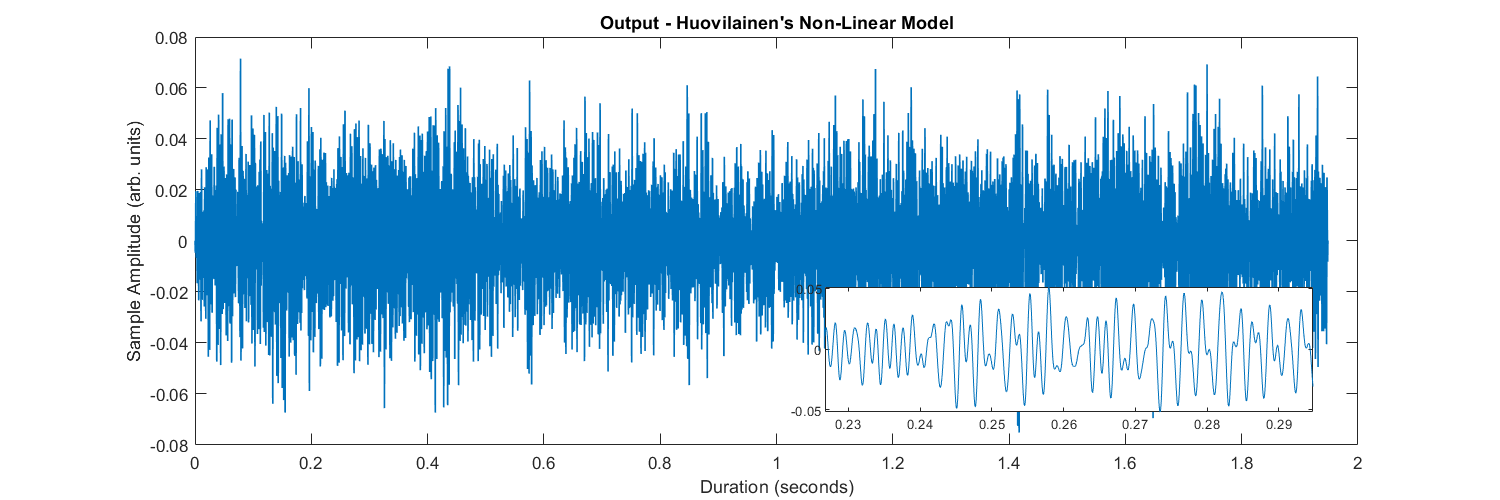

plot(t(1:end-1), out_nonlinear, 'LineWidth', 1);
title("Output - Huovilainen's Non-Linear Model");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.175 0.325 0.25])
box on % put box around new pair of axes
plot(t(10000:13000), out_nonlinear(10000:13000)) % plot on new axes
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

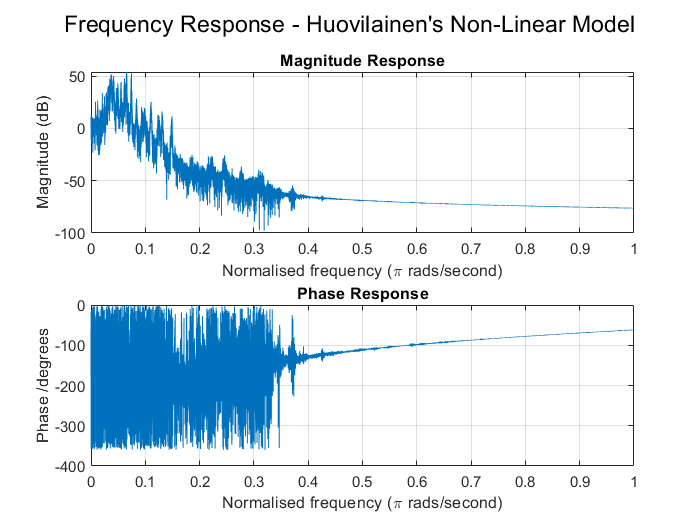

[magnt_nonlinear, phase_nonlinear] = f_plotFrqcResp(out_nonlinear, range_f, Fs, "Frequency Response - Huovilainen's Non-Linear Model", false, false, false);

# Implementing the Automating Gain Stage - Stevens's Power Rule

This version implements the gain stage using Stevens's power rule

This version makes delays (accounted for in sequential processing) more noticeable.

The delays could potentially be reduced to much less with a direct-gain method, which eliminates the need for log-antilog conversions.

Pseudocode:

We can then plot the results below.

### Calculating signal energy

We can also find the energy of the input & output signal.

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

# Implementing the Automating Gain Stage v4.1

This 'version' allows the audio to be 'streamed' as buffers of 1024 samples per buffer (or dynamically allocated).

This should ensure smooth (relative) transition between the current, previous, and next buffers, and adapts v4.0.

From MovingRMS.m the formula used for calculating RMS is:


$$V_{rms}[k] = \sqrt{\frac{1}{N} \sum_{n=1}^{N} v_n[k]^2}$$


This can be seen here: [Energies | Free Full-Text | A Memory-Efficient True-RMS Estimator in a Limited-Resources Hardware | HTML (mdpi.com)](https://www.mdpi.com/1996-1073/12/9/1699/htm)

IDEA:

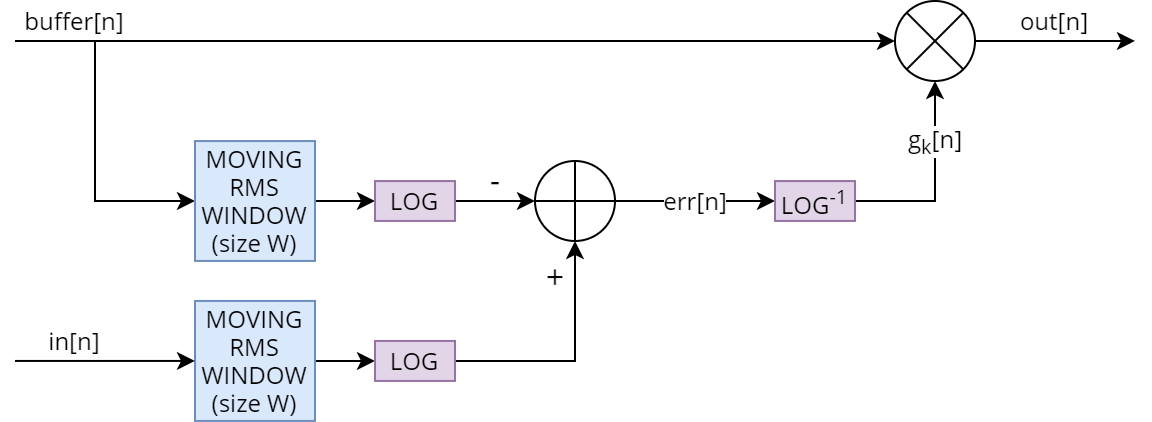

Program works in MATLAB since everything is sequential, therefore delay is expected. However, can we be a bit more specific?

### Calculating signal energy

We can also find the energy of the input & output signal.


$$E = \sum_{n=-\infty}^{+\infty} x[n]^2 \equiv \sum_{n=0}^{N} x[n]^2 (N<\infty)$$


We can also divide the results by N to get a mean square value. This normalises the energy within the window. This is redundant, however, and could be ignored & use the regular sum instead.

NB: The moving average method fails, likely because the waveform in audio signals are mostly periodic, and finding an average over a large sample window would likely overtake a large number of cycles. Taking an average of this would result in a zero average. Hence, RMS is used instead.

The current method can be represented as the following diagram.

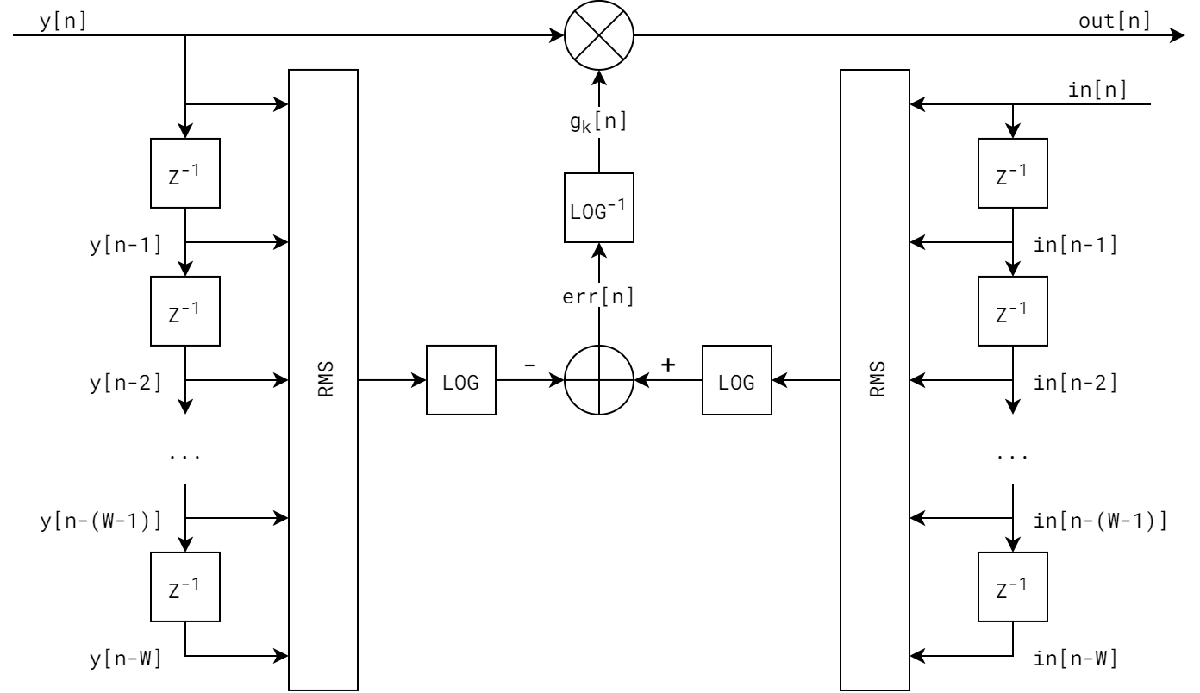

EDIT: After further discussions, given dB the RMS values would be subtracted (ie ref - out), so our feedforward AGC method is correct.

However to solidify this let us implement it in dB form. To be continued?

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

## RMS Function investigation (bonus)

Although not required, it is worth investigating whether writing our own RMS calculation function would result in a smaller computation time, or otherwise, compared to the built-in DSP add-on function.

If less, then it is worth using our own implementation. (See original code for implementation)

It was found that my code is always faster than MATLAB's runtime. This might be due to MATLAB doing many checks in its code while my version just jumps right in.

This will be useful in the plugin real-time implementation.

# Implementing the Automating Gain Stage v5.1

This version implements the same as AG stage 4.1, however does so sample by sample.

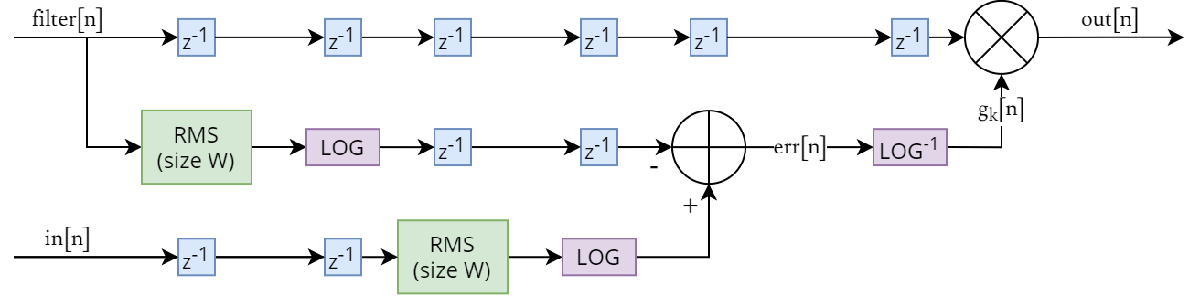

This version makes delays (accounted for in sequential processing) more noticeable.

The delays could potentially be reduced to much less with a direct-gain method, which eliminates the need for log-antilog conversions.

Pseudocode:


in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

% size_window = 1024 * 2^5; %22050; %size(in_audio, 1);
size_window = 44100;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_rms_log = zeros(0, 2);

% For testing purposes
% nrg_input = zeros(0, 2);
% nrg_filtr = zeros(0, 2);
% nrg_outpt = zeros(0, 2);
% seq_gain = zeros(0, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% 2) Calculate RMS values
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_rms_filtr = 20 * log10(rms_filtr);
    log_rms_input = 20 * log10(rms_input);
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_rms = log_rms_input - log_rms_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_rms ./ 20);
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_rms_log(end+1, :) = out_filtered(i_sample, :) .* gain_corrector;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
end
toc

We can then plot the results below.

figure;
hold on;
% plot(t(1:end-1), out_rms_log(:, 1));
plot(out_rms_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_rms_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the energy of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)
e_outFiltered = mean(out_filtered(:, :) .^ 2)
e_outRms = mean(out_rms_log(:, :) .^ 2)

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

[magnt_rmsLog, phase_rmsLog] = f_plotFrqcResp(out_rms_log, range_f, Fs, "RMS", false, true);

Let us plot the spectogram as well.

# Implementing the Automating Gain Stage v5.1.1

This version is the same as v5.1.1 but attempts a feedforward-feedback system.

Pseudocode:

Main code

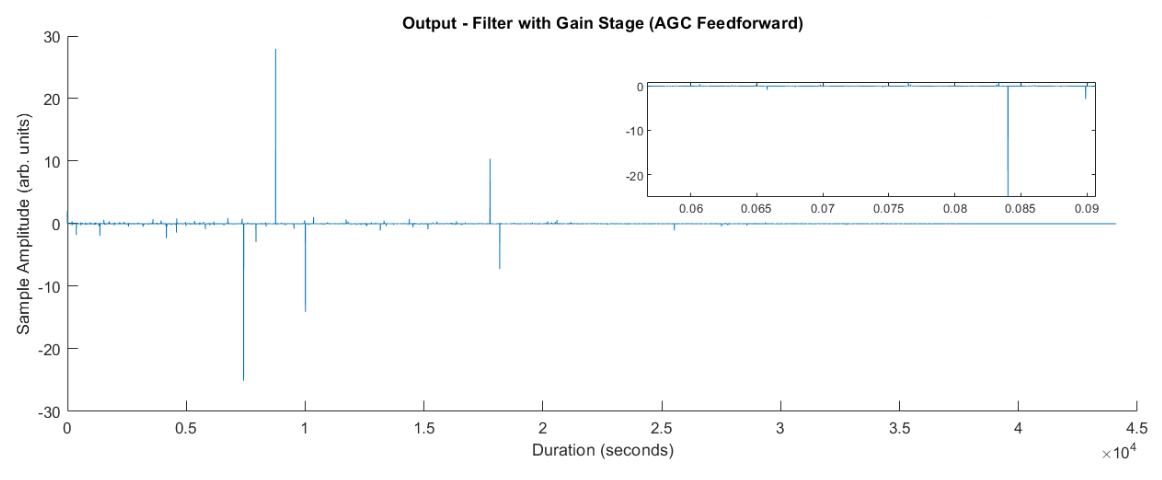

It is obvious that this is NOT what is expected...

# Implementing the Automating Gain Stage v5.1.2

This version feeds the output back to itself instead.

Pseudocode:

Main code

NB: We choose a reasonably small feedback delay window size, since choosing a big window means averaging a large chunk of signal (and that results in zero or a small magnitude!) Ideally the waveform is smoothened and reduces phase/magnitude distortion.

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

size_window = 44100;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_feedbk = zeros(0, 2);

%%% Stores feedback value
sz_mem_feedbk = 3; % Size of feedback window
mem_outFeedbk = zeros(sz_mem_feedbk, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% 2) Calculate RMS values
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_rms_filtr = 20 * log10(rms_filtr);
    log_rms_input = 20 * log10(rms_input);
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_rms = log_rms_input - log_rms_filtr;
    % Converts err value to gain
    gain_corrector = real(10 .^ (err_rms ./ 20));
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_current = out_filtered(i_sample, :) .* gain_corrector;
   
    %%% 6) Find average of current and feedback outputs
    %mem_outFeedbk2_temp = mem_outFeedbk2;
    %mem_outFeedbk2 = mem_outFeedbk;
    out_averaged = [out_current(:, 1) + sum(mem_outFeedbk(:, 1)), ...
                    out_current(:, 2) + sum(mem_outFeedbk(:, 2))  ...
                    ] ./ (sz_mem_feedbk + 1);
    mem_outFeedbk = [mem_outFeedbk(2:end, :); out_averaged];
    out_feedbk(end+1, :) = out_averaged;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
    %mem_outFeedbk = out_rms_log(end, :);
end
toc

We can then plot the results below.

figure;
hold on;
plot(t(1:end-1), out_feedbk(:, 1));
%plot(out_feedbk(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000:16000), out_feedbk(10000:16000))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the power of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)
e_outFiltered = mean(out_filtered(:, :) .^ 2)
e_outFbk = mean(out_feedbk(:, :) .^ 2)

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

[magnt_rmsFbk, phase_rmsFbk] = f_plotFrqcResp(out_feedbk, range_f, Fs, "RMS", false, true);

range_f; % Serves no purpose - just placing breakpoint here!

With all of this we can plot the spectra and compare the distortions.

range_f_normalised = range_f * (2 * pi) / Fs;

% Assign default values
% plot_y_frqc = 10 * log( magnt_out(range_f) );
% plot_y_phas = mod(( phase_out(range_f) * 180/pi ), -360);
% plot_x = range_f_normalised / pi;
% label_x = "Normalised frequency (\pi rads/second)";
% label_y_frqc = "Magnitude (dB)";

figure;

% switch nargin
% case 6
%     if bool_x_useLog
%         plot_x = range_f;
%         label_x = "Frequency (Hz)";
%     end
%     if bool_y_useLin
%         plot_y_frqc = magnt_out(range_f);
%         label_y_frqc = "Magnitude (arb.)";
%     end
% case 5
%     if bool_y_useLin
%         plot_y_frqc = magnt_out(range_f);
%         label_y_frqc = "Magnitude (arb.)";
%     end
% end

%%% Plots magnitude response
sgtitle("PLOT IT")
subplot(2, 1, 1);
hold on;
plot(   range_f_normalised / pi, ...
        10 * log( magnt_nonlinear(range_f) ));
plot(   range_f_normalised / pi, ...
        10 * log( magnt_rmsLog(range_f) ));
plot(   range_f_normalised / pi, ...
        10 * log( magnt_rmsFbk(range_f) ));
%set(gca, 'XScale', 'log')

title("Magnitude Response"); %"Spectrum (FFT)"
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on

%%% Plots phase response
subplot(2, 1, 2);
hold on;
plot(   range_f_normalised / pi, ...
        mod(( phase_nonlinear(range_f) * 180/pi ), -360));
plot(   range_f_normalised / pi, ...
        mod(( phase_rmsLog(range_f) * 180/pi ), -360));
plot(   range_f_normalised / pi, ...
        mod(( phase_rmsFbk(range_f) * 180/pi ), -360));
%set(gca, 'XScale', 'log')

title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

# Implementing the Automating Gain Stage v5.1.3

This version feeds the output back to itself instead.

Pseudocode:

Main code

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

size_window = 44100;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_feedbk = zeros(0, 2);

%%% Stores feedback value
sz_mem_feedbk = 4;
mem_outFeedbk = zeros(sz_mem_feedbk, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% T) Get FFT of buffer values
    seq_proc_filtr_fft = abs(fft(seq_proc_filtr));
    seq_proc_filtr_fft = log(seq_proc_filtr_fft);
    seq_proc_input_fft = abs(fft(seq_proc_input));
    seq_proc_input_fft = log(seq_proc_input_fft);
    
    %%% T) Get IFFT of values
    seq_proc_filtr = ifft(seq_proc_filtr_fft);
    seq_proc_input = ifft(seq_proc_input_fft);
    
    %%% 2) Calculate RMS values
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_rms_filtr = 20 * log10(rms_filtr);
    log_rms_input = 20 * log10(rms_input);
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_rms = log_rms_input - log_rms_filtr;
    % Converts err value to gain
    gain_corrector = real(10 .^ (err_rms ./ 20));
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_current = out_filtered(i_sample, :) .* gain_corrector;
    out_averaged = out_current;
   
    %%% 6) Find average of current and feedback outputs
    %mem_outFeedbk2_temp = mem_outFeedbk2;
    %mem_outFeedbk2 = mem_outFeedbk;
%     out_averaged = [out_current(:, 1) + sum(mem_outFeedbk(:, 1)), ...
%                     out_current(:, 2) + sum(mem_outFeedbk(:, 2))  ...
%                     ] ./ (sz_mem_feedbk + 1);
%     mem_outFeedbk = [mem_outFeedbk(2:end, :); out_averaged];
    out_feedbk(end+1, :) = out_averaged;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
    %mem_outFeedbk = out_rms_log(end, :);
end
toc

We can then plot the results below.

figure;
hold on;
% plot(t(1:end-1), out_rms_log(:, 1));
plot(out_feedbk(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_feedbk(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the power of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)
e_outFiltered = mean(out_filtered(:, :) .^ 2)
e_outFbk = mean(out_feedbk(:, :) .^ 2)

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

[magnt_rmsFbk, phase_rmsFbk] = f_plotFrqcResp(out_feedbk, range_f, Fs, "RMS", false, true);

# Implementing the Automating Gain Stage v5.1.2 - Shortcut Gain

This version exploits the mathematical equivalence of log-antilog relations & applies the gain directly.

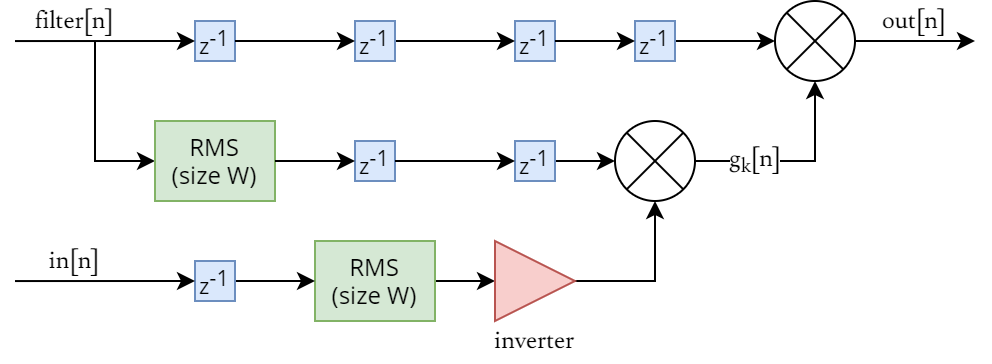

This version eliminates the need for log-antilog conversions, and reduces the number of delays required.

# Implementing the Automating Gain Stage v8 (derived from v5.1) [ON HOLD]

This version implements the same as AG stage 5.1, however in RMS calculations each sample also looks at values AFTER itself.

# Implementing the Automating Gain Stage v9

After further research, it was found that the algorithm used in v5.1 is actually compliant with ITU's method (see document).

This version attempts to apply K-weighting (or similar) to the signal before finding the RMS.

NOTE: This method might not be necessary; do we care about what we can hear & not the signal itself? This delves into psychoacoustics.

Pseudocode:

Main code:

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

% size_window = 1024 * 2^5; %size(in_audio, 1);
size_window = 44100*2;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_Lk_log = zeros(0, 2);

%%% Sets A-weighting filter
% weightFilt = weightingFilter("A-weighting");
% weightFilt = weightingFilter("C-weighting");
weightFilt = weightingFilter("K-weighting", Fs);


%%% TEST: Apply 'exponential' weight
arr_weight = linspace(0, 1, size_window);
arr_weight = [arr_weight; arr_weight]';

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% TEST: A-weighting stage
    seq_proc_aW_filtr = weightFilt(seq_proc_filtr);
    seq_proc_aW_input = weightFilt(seq_proc_input);
    
    seq_proc_aW_filtr = seq_proc_aW_filtr .* arr_weight;
    seq_proc_aW_input = seq_proc_aW_input .* arr_weight;
    
    %%% 2) Calculate RMS values
    Lk_filtr = [ rms(seq_proc_aW_filtr(:, 1)), rms(seq_proc_aW_filtr(:, 2)) ];
    Lk_input = [ rms(seq_proc_aW_input(:, 1)), rms(seq_proc_aW_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_Lk_filtr = 10 * log10(Lk_filtr);
    log_Lk_input = 10 * log10(Lk_input);
    % Standard "ITU-R BS.1770-3" requires subtracting these LOG vals with –0.691
    % However, we intend to subtract the values together, so this becomes redundant
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_Lk = log_Lk_input - log_Lk_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_Lk ./ 10);
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_Lk_log(end+1, :) = out_filtered(i_sample, :) .* gain_corrector;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
end
toc

We can then plot the results below.

figure;
hold on;
plot(out_Lk_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_Lk_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the energy of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)
e_outFiltered = mean(out_filtered(:, :) .^ 2)
e_outRms = mean(out_Lk_log(:, :) .^ 2)

We attempted to find the RMS loudness BUT remember that we are considering an entire waveform, so RMS is not applicable

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

f_plotFrqcResp(out_Lk_log, range_f, Fs, "RMS");

# Implementing the Automating Gain Stage - ITU

This version implements the Leq(RLB) algorithm and the K-filter based on the ITU document.

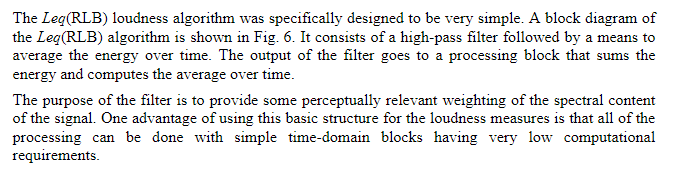

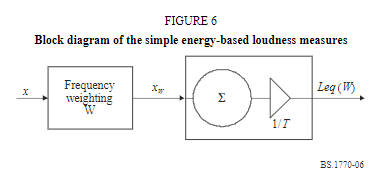

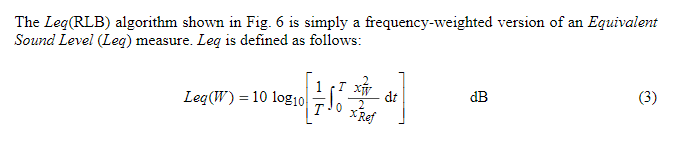

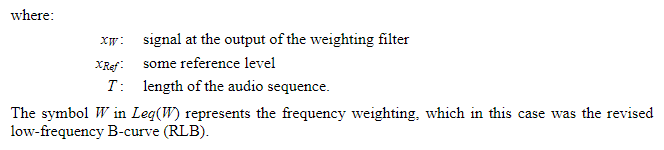

Let us rewrite this for discrete-time:


$$\textrm{Leq}\left(w\right)=20\log_{10} \sqrt{\frac{1}{N}\sum_{n=0}^{N-1} {\left(\frac{x_w \left\lbrack n\right\rbrack }{20\mu \;}\right)}^{2\;} }$$


NB: mathematically equivalent as the 10log10() variant

Consider: reference signal here != reference signal in AGC??

Reference signal for Leq(RLB) might be 1 arb??

If so, then our original algorithm is pretty close, AND now we have literature to back this up!!

Further discussion 210409 - yep, the K-weighting LKFS is derived from Leq()!

---

Pseudocode:

## RLB Filter

Fs_filter = 44100;

Let us now define the RLB filter.

Before we get into the main code, let us define the RLB coefficients for 44.1kHz fs as defined by Ward:

[fil_rlb_coef_b, fil_rlb_coef_a] = f_getCoef_rlb(Fs_filter); 
[magnt_fil_rlb, ~] = freqz(fil_rlb_coef_b, fil_rlb_coef_a, Fs_filter/2);

Observe that only omega needs changing to obtain the same frequency responses.

## Pre-K Filter

Let us also define the RLB coefficients for 44.1kHz fs as defined by Ward:

[fil_preK_coef_b, fil_preK_coef_a] = f_getCoef_preK(Fs_filter); 
[magnt_fil_preK, ~] = freqz(fil_preK_coef_b, fil_preK_coef_a, Fs_filter/2);

Let us now plot both at the same time

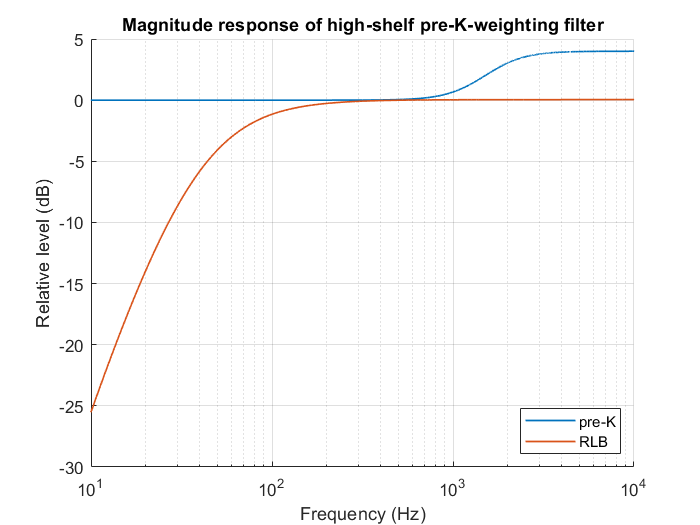

figure;
hold on;
plot(1:Fs_filter/2, 20 * log10(abs(magnt_fil_preK)), "LineWidth", 1, "DisplayName", "pre-K");
plot(1:Fs_filter/2, 20 * log10(abs(magnt_fil_rlb)), "LineWidth", 1, "DisplayName", "RLB");
legend('Location','southeast')
grid on
hold off;
title("Magnitude response of high-shelf pre-K-weighting filter")
ylabel("Relative level (dB)"); ylim([-30, 5])
set(gca, 'XScale', 'log')
xlabel("Frequency (Hz)"); xlim([10, 10000])

## Combined K-filter!

Both filters can then be cascaded to form the K filter:

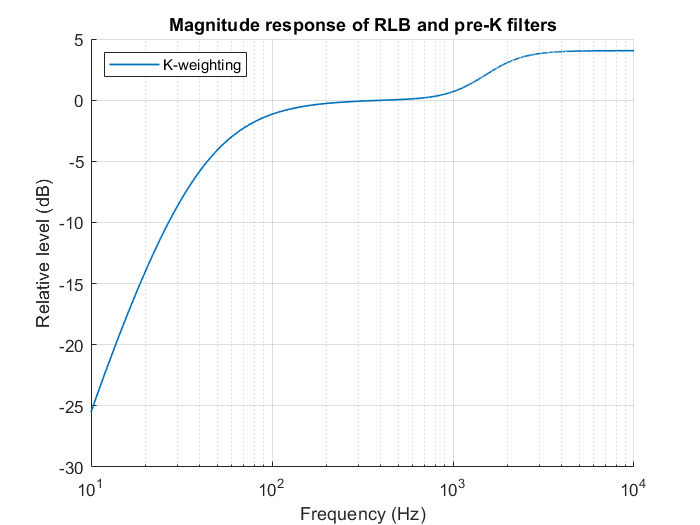


magnt_fil_K = magnt_fil_preK .* magnt_fil_rlb;
figure;
hold on
plot(1:Fs_filter/2, 20 * log10(abs(magnt_fil_K)), "LineWidth", 1, "DisplayName", "K-weighting");
grid on;
legend('Location','northwest')
title("Magnitude response of RLB and pre-K filters")
ylabel("Relative level (dB)"); % ylim([-30, 50])
set(gca, 'XScale', 'log')
xlabel("Frequency (Hz)"); xlim([10, 10000])

---

Main code:

in_audio = zeros(44100, 1);
in_audio(1, :) = 1;
% coefWeight = f_coefWeight(Fc, Fs);
out_nonlinear = f_runFilter(in_audio, duration, Fs, f_coefWeight(440, 44100), 3.99, "nonlinear");
% out_filtered = 0.1 * [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];

% [in_audio, ~] = audioread("waterNight_original.wav");
% in_audio = [in_audio(:, 1), in_audio(:, 1)];
out_filtered = out_nonlinear';

sz_channel = size(in_audio, 2);

% size_window = 1024 * 2^5; %size(in_audio, 1);
size_window = 44100*0.4; % 0.4s from ITU document
% Stores initial memory for initialisation
% seq_mem_input = zeros((size_window - 1), 2);
% seq_mem_filtr = zeros((size_window - 1), 2);
% seq_mem_outpt = zeros((size_window - 1), 2);
out_Leq_log = zeros(0, sz_channel);


p0_ref = 20e-6;

mem_avg = zeros(1, sz_channel);
factor_avg = 0.5; % Factor for moving average at output


seq_proc_filtr = zeros((size_window - 1), sz_channel);
seq_proc_input = zeros((size_window - 1), sz_channel);

tic;
for i_sample = 1:length(in_audio)
    
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_proc_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_proc_input; in_audio(i_sample, :)];
    
    % Applies RLB weighting
    seq_proc_K_filtr = filter(fil_rlb_coef_b, fil_rlb_coef_a, seq_proc_filtr);
    seq_proc_K_input = filter(fil_rlb_coef_b, fil_rlb_coef_a, seq_proc_input);
    % Applies pre-filter weighting
    seq_proc_K_filtr = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_K_filtr);
    seq_proc_K_input = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_K_input);
    
    %%% 2) Calculate Leq values
    % Find the total summation inside formula
    Leq_filtr = sum( (seq_proc_K_filtr(:, :) ./ p0_ref) .^ 2);
    Leq_input = sum( (seq_proc_K_input(:, :) ./ p0_ref) .^ 2);
    % Obtain linear form
    Leq_filtr = sqrt(Leq_filtr /size_window);
    Leq_input = sqrt(Leq_input /size_window);
    % Sums the two channels together
    Leq_filtr = sum(Leq_filtr);
    Leq_input = sum(Leq_input);
    % Converts linear value to LOG
    log_Leq_filtr = 20 * log10(Leq_filtr);
    log_Leq_input = 20 * log10(Leq_input);
    
    % Standard "ITU-R BS.1770-3" requires subtracting these LOG vals with –0.691
    % However, we intend to subtract the values together, so this becomes redundant
    
    %%% 3) Calculate the correcting gain
    % Find the error value
    err_Leq = log_Leq_input - log_Leq_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_Leq ./ 20);
    if abs(gain_corrector) == Inf % Prevents infinite gain - set to max floating point
        gain_corrector = sign(gain_corrector) * realmax;
    elseif isnan(abs(gain_corrector)) % Corrects NaN values - set to zero
        gain_corrector = 0;
    end
    
    %%% 4) Apply gain to delayed filter output at sample n
    out_now = out_filtered(i_sample, :) .* gain_corrector; % Get current output
    % Applies expo average filter
    out_now = out_now * factor_avg; % A larger factor considers the now value more
    out_Leq_log(end+1, :) = out_now + ((1 - factor_avg) * mem_avg);
    mem_avg = out_Leq_log(end, :);
    
    %% Applies averaging filter
    %gain_corrector_now = (factor_avg * gain_corrector) + ((1 - factor_avg) * mem_avg);
    %%%% 4) Apply gain to delayed filter output at sample n
    %out_Leq_log(end+1, :) = out_filtered(i_sample, :) .* gain_corrector_now;
    %mem_avg = gain_corrector_now;
    
    %%% 5) Adjust memory
    seq_proc_filtr = seq_proc_filtr(2:end, :);
    seq_proc_input = seq_proc_input(2:end, :);
        
end
toc

Elapsed time is 36.631739 seconds.


We can then plot the results below.

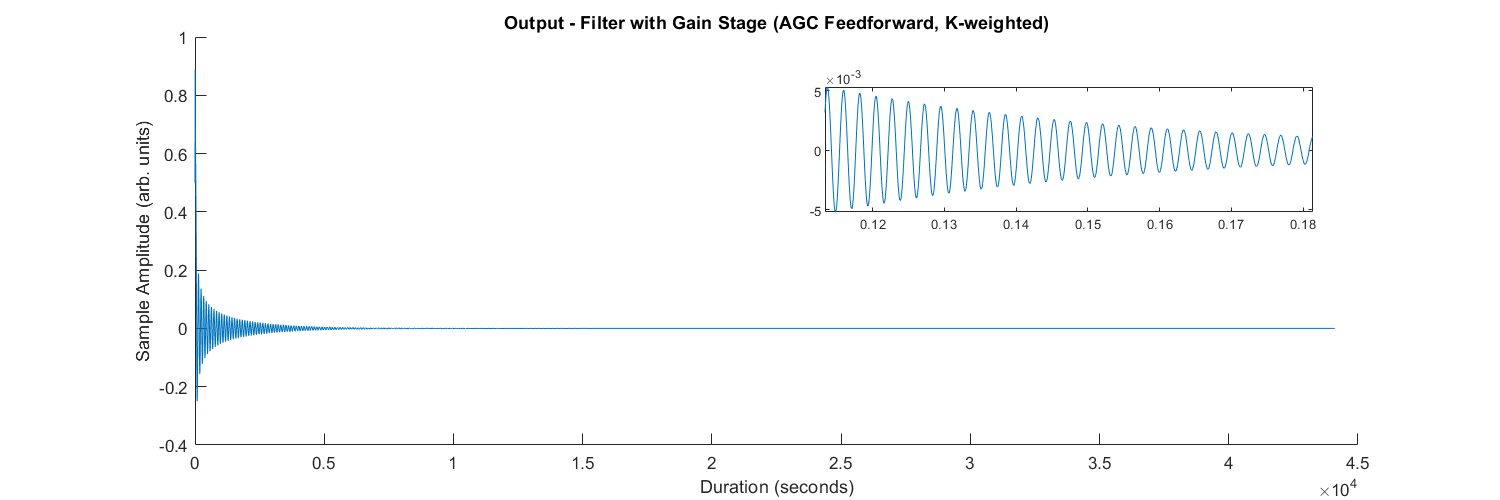

figure;
hold on;
plot(out_Leq_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward, K-weighted)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_Leq_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### EMA plot

We can also find the loudness via EMA - this is used for evaluation of results

% Applies Ward's moving avg filtr
seq_ema_L_filtr = zeros(0, sz_channel);
seq_ema_L_input = zeros(0, sz_channel);
seq_ema_L_outpt = zeros(0, sz_channel);

const_ema = 1; %0.125;
coef_ema = 1 - exp(-1 / (Fs * const_ema));
mem_ema_L_input = zeros(1, sz_channel);
mem_ema_L_filtr = zeros(1, sz_channel);
mem_ema_L_outpt = zeros(1, sz_channel);

%%% EMA: Finds EMA sequence & stores them
for i_sample = 1:length(in_audio)
    % Finds EMA of filtr
    mem_ema_L_filtr = (coef_ema * (out_filtered(i_sample, :) .^ 2)) + ((1 - coef_ema) * mem_ema_L_filtr);
    seq_ema_L_filtr(end+1, :) = mem_ema_L_filtr;
    % Finds EMA of input
    mem_ema_L_input = (coef_ema * (in_audio(i_sample, :) .^ 2)) + ((1 - coef_ema) * mem_ema_L_input);
    seq_ema_L_input(end+1, :) = mem_ema_L_input;
    
    % Finds EMA of outut
    mem_ema_L_outpt = (coef_ema * (out_Leq_log(i_sample, :) .^ 2)) + ((1 - coef_ema) * mem_ema_L_outpt);
    seq_ema_L_outpt(end+1, :) = mem_ema_L_outpt;
end


And plot the loudness obtained

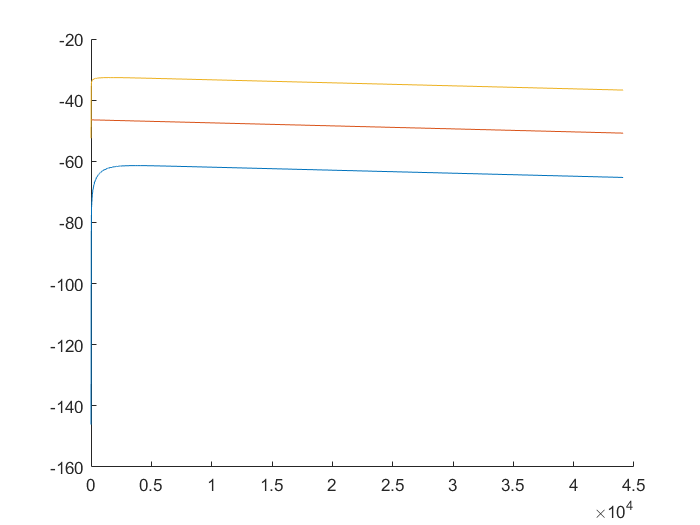

figure;
hold on;
plot(10 * log10(seq_ema_L_filtr(:, 1)))
plot(10 * log10(seq_ema_L_input(:, 1)))
plot(10 * log10(seq_ema_L_outpt(:, 1)))

### Analyse frequency content

We can also analyse the frequency components in this output waveform

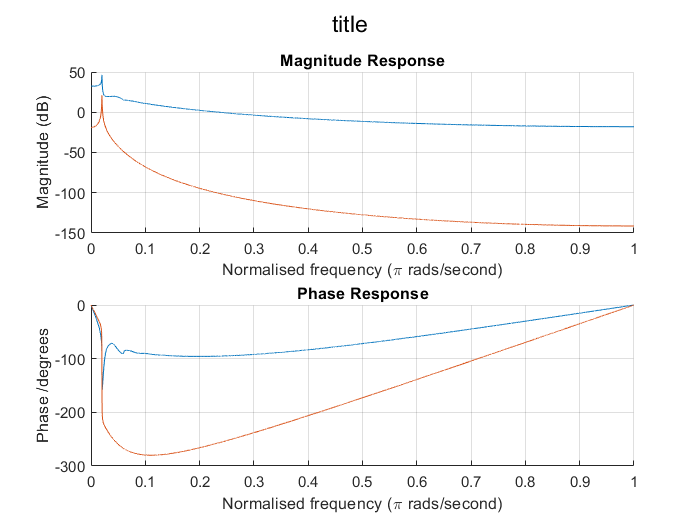

% f_plotFrqcResp(out_Leq_log, range_f, Fs, "RLB-weighted", false, true);
% f_plotFrqcResp(out_filtered, range_f, Fs, "RLB-weighted", false, true);
% f_plotFrqcResp(in_audio, range_f, Fs, "RLB-weighted", false, true);
[magnt_out_Leq_log, phase_out_Leq_log, range_f_normalised] = f_getFrqcResp(out_Leq_log, range_f, Fs);
[magnt_out_filtered, phase_out_filtered, ~] = f_getFrqcResp(out_filtered, range_f, Fs);
figure;
f_plotFrqcResp_core([magnt_out_Leq_log(:, 1), magnt_out_filtered(:, 1)], [phase_out_Leq_log(:, 1), phase_out_filtered(:, 1)], range_f, range_f_normalised, "title", false, true)

As shown in the frequency response, the magnitudes and frequencies where f<fc remain the same shape and structure. However frequencies above the cutoff are distorted, and phases above the cutoff are distorted as well. This is expected behavior as, given a LPF, frequencies which we intend to remain in the stopband will be accentuated, and contributes to the overall loudness of the time signal.

However NB is there a way to reduce this distortion?

# **EMA method v3**

**Time-weighting method**

Main code:

% [in_audio, ~] = audioread("waterNight_original.wav");
% in_audio = zeros(44100, 2);
% in_audio(1, :) = 1;
% in_audio = [in_audio(1:44100)', in_audio(1:44100)'];
% out_filtered = [out_nonlinear(1:44100)', out_nonlinear(1:44100)'];

% [in_audio, ~] = audioread("waterNight_original.wav");
% % in_audio = zeros(44100, 2);
% % in_audio(1, :) = 1;
% in_audio = [in_audio(1:44100*7)', in_audio(1:44100*7)'];
% out_filtered = [out_nonlinear(1:44100*7)', out_nonlinear(1:44100*7)'];

% size_window = 44100*0.4; % 0.4s from ITU document
% Stores initial memory for initialisation
% seq_mem_input = zeros((size_window - 1), 2);
% seq_mem_filtr = zeros((size_window - 1), 2);
% seq_mem_outpt = zeros((size_window - 1), 2);
out_L_ema = zeros(0, sz_channel);
out_L_ema_noAvg = zeros(0, sz_channel);

sz_channel = size(in_audio, 2);

p0_ref = 20e-6;

mem_avg = zeros(1, sz_channel);
factor_avg = 0.5; % Factor for moving average at output


% seq_proc_filtr = zeros((size_window - 1), sz_channel);
% seq_proc_input = zeros((size_window - 1), sz_channel);

seq_buf_filtr_preK = zeros(2, sz_channel); % Stores buffer for filtr algorithm
seq_buf_filtr_rlb = zeros(2, sz_channel); % Stores buffer for filtr algorithm
seq_buf_input_preK = zeros(2, sz_channel); % Stores buffer for filtr algorithm
seq_buf_input_rlb = zeros(2, sz_channel); % Stores buffer for filtr algorithm


% Applies Ward's moving avg filtr
plt_ema_L_filtr = zeros(0, sz_channel);
plt_ema_L_input = zeros(0, sz_channel);
plt_ema_L_outpt = zeros(0, sz_channel);

const_ema = 0.125; %0.125;
coef_ema = 1 - exp(-1 / (Fs * const_ema));
mem_ema_L_input = zeros(1, sz_channel);
mem_ema_L_filtr = zeros(1, sz_channel);
mem_ema_L_outpt = zeros(1, sz_channel);


tic;
for i_sample = 1:length(in_audio)
    
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = out_filtered(i_sample, :);
    seq_proc_input = in_audio(i_sample, :);
    
    % Applies pre-filter weighting
%     [seq_proc_K_filtr, seq_buf_filtr_preK] = f_1dFilter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_filtr, seq_buf_filtr_preK);
%     [seq_proc_K_input, seq_buf_input_preK] = f_1dFilter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_input, seq_buf_input_preK);
%     % Applies RLB weighting
%     [seq_proc_K_filtr, seq_buf_filtr_rlb] = f_1dFilter(fil_rlb_coef_b, fil_rlb_coef_a, seq_proc_K_filtr, seq_buf_filtr_rlb);
%     [seq_proc_K_input, seq_buf_input_rlb] = f_1dFilter(fil_rlb_coef_b, fil_rlb_coef_a, seq_proc_K_input, seq_buf_input_rlb);

    % Applies pre-filter weighting
    [seq_proc_K_filtr, seq_buf_filtr_preK]  = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_filtr, seq_buf_filtr_preK, 1);
    [seq_proc_K_input, seq_buf_input_preK]  = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_input, seq_buf_input_preK, 1);
    % Applies RLB weighting
    [seq_proc_K_filtr, seq_buf_filtr_rlb]  = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_K_filtr, seq_buf_filtr_rlb, 1);
    [seq_proc_K_input, seq_buf_input_rlb]  = filter(fil_preK_coef_b, fil_preK_coef_a, seq_proc_K_input, seq_buf_input_rlb, 1);
    
    
%     seq_proc_K_filtr = seq_proc_filtr;
%     seq_proc_K_input = seq_proc_input;
    
    %%% EMA: Finds EMA sequence & stores them
    % Finds EMA of filtr
    mem_ema_L_filtr = (coef_ema * (seq_proc_K_filtr .^ 2)) + ((1 - coef_ema) * mem_ema_L_filtr);
    % Finds EMA of input
    mem_ema_L_input = (coef_ema * (seq_proc_K_input .^ 2)) + ((1 - coef_ema) * mem_ema_L_input);
    % Converts vals to log form
    log_Leq_filtr = 10 * log10(mem_ema_L_filtr);
    log_Leq_input = 10 * log10(mem_ema_L_input);
    
    % Stores values for plotting
    plt_ema_L_filtr(end+1, :) = mem_ema_L_filtr;
    plt_ema_L_input(end+1, :) = mem_ema_L_input;
    
    
    %%% 3) Calculate the correcting gain
    % Find the error value
    err_L_ema = log_Leq_input - log_Leq_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_L_ema ./ 20);
    % Corrects value
    if abs(gain_corrector) == Inf % Prevents infinite gain - set to max floating point
        gain_corrector = sign(gain_corrector) * realmax;
    elseif isnan(abs(gain_corrector)) % Corrects NaN values - set to zero
        gain_corrector = 0;
    end
    
    %%% 4) Apply gain to delayed filter output at sample n
    out_now = out_filtered(i_sample, :) .* gain_corrector; % Get current output
    out_L_ema_noAvg(end+1, :) = out_now;
    % Applies expo average filter
    out_now = out_now * factor_avg; % A larger factor considers the now value more
    out_L_ema(end+1, :) = out_now + ((1 - factor_avg) * mem_avg);
    mem_avg = out_L_ema(end, :);
    
    %%% 5) Adjust memory
%     seq_proc_filtr = seq_proc_filtr(2:end, :);
%     seq_proc_input = seq_proc_input(2:end, :);
    
    % Finds EMA of filtr
    mem_ema_L_outpt = (coef_ema * (out_L_ema(end, :) .^ 2)) + ((1 - coef_ema) * mem_ema_L_outpt);
    plt_ema_L_outpt(end+1, :) = mem_ema_L_outpt;
end
toc

Elapsed time is 0.553454 seconds.


We can then plot the results below.

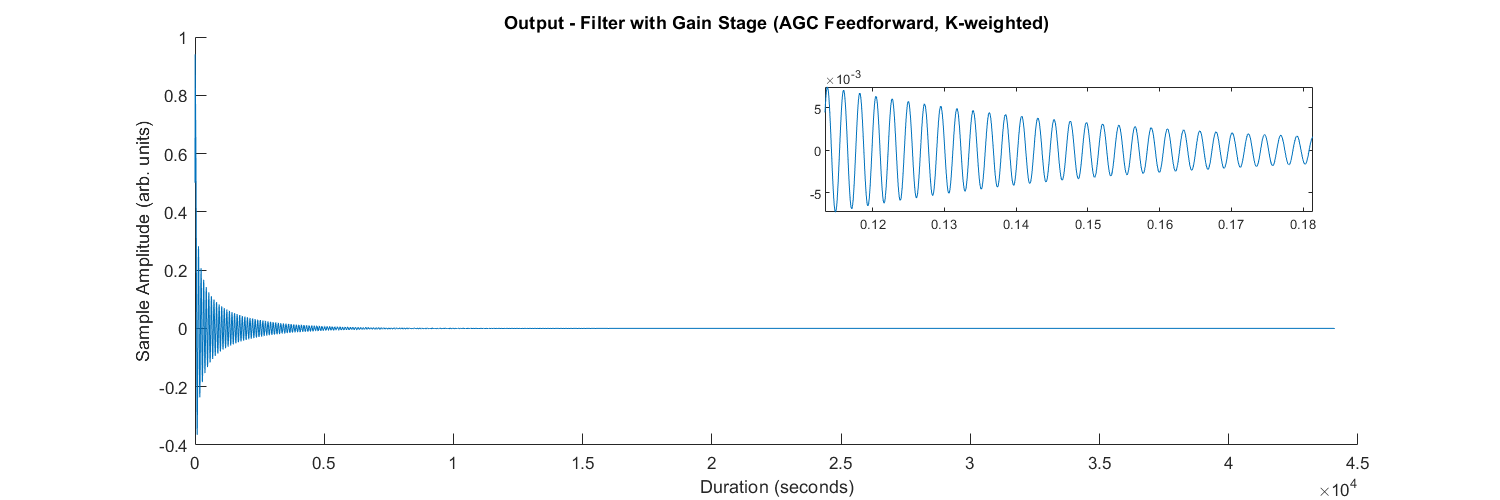

figure;
hold on;
plot(out_L_ema(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward, K-weighted)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_L_ema(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

Let us also plot the frequency response.

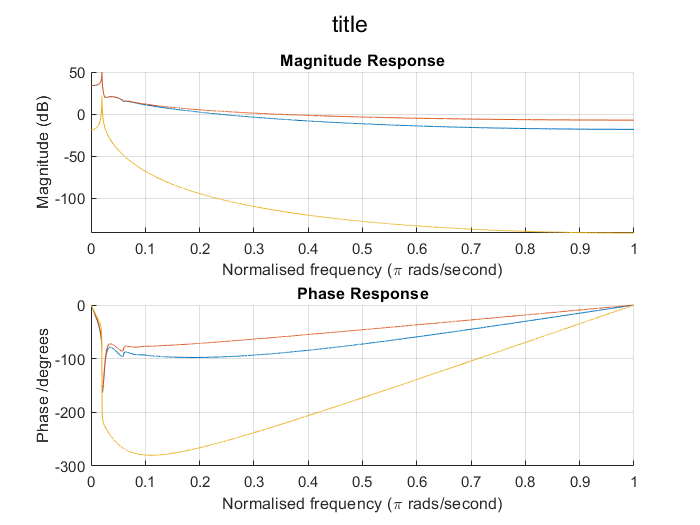

%f_plotFrqcResp(out_L_ema, range_f, Fs, "Gain-applied, EMA time-weighted", false, true, false);
%f_plotFrqcResp(out_filtered, range_f, Fs, "Filtered signal", false, true, false);
[magnt_out_L_ema_noAvg, phase_out_L_ema_noAvg, ~] = f_getFrqcResp(out_L_ema_noAvg, range_f, Fs);
[magnt_out_L_ema, phase_out_L_ema, range_f_normalised] = f_getFrqcResp(out_L_ema, range_f, Fs);
[magnt_out_filtered, phase_out_filtered, ~] = f_getFrqcResp(out_filtered, range_f, Fs);
figure;
f_plotFrqcResp_core([magnt_out_L_ema(:, 1), magnt_out_L_ema_noAvg(:, 1), magnt_out_filtered(:, 1)], [phase_out_L_ema(:, 1), phase_out_L_ema_noAvg(:, 1), phase_out_filtered(:, 1)], range_f, range_f_normalised, "title", false, true)

The EMA-weighted method uses less memory, takes less computation time, and shows a magnitude/phase response much closer to that of the filtered signal.

There is a visible distortion from Fc onwards - frequencies below Fc retain their frequency responses. 

Let us compare the RMS method with EMA method

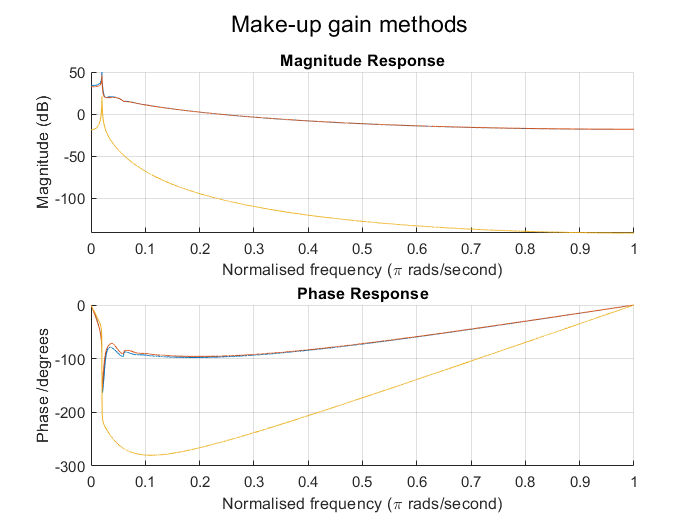

figure;
f_plotFrqcResp_core([magnt_out_L_ema(:, 1), magnt_out_Leq_log(:, 1), magnt_out_filtered(:, 1)], [phase_out_L_ema(:, 1), phase_out_Leq_log(:, 1), phase_out_filtered(:, 1)], range_f, range_f_normalised, "Make-up gain methods", false, true)

% f_plotFrqcResp_core(, phase_out_filtered, range_f, range_f_normalised, "title", false, true)

Test filter

in_audio = zeros(10, 2);
in_audio(1, :) = 1;
test_outFilter_mtl = filter(fil_rlb_coef_b, fil_rlb_coef_a, in_audio)

test_outFilter_mtl =     0.9996    0.9996
   -0.0108   -0.0108
   -0.0107   -0.0107
   -0.0107   -0.0107
   -0.0106   -0.0106
   -0.0105   -0.0105
   -0.0104   -0.0104
   -0.0103   -0.0103
   -0.0102   -0.0102
   -0.0101   -0.0101


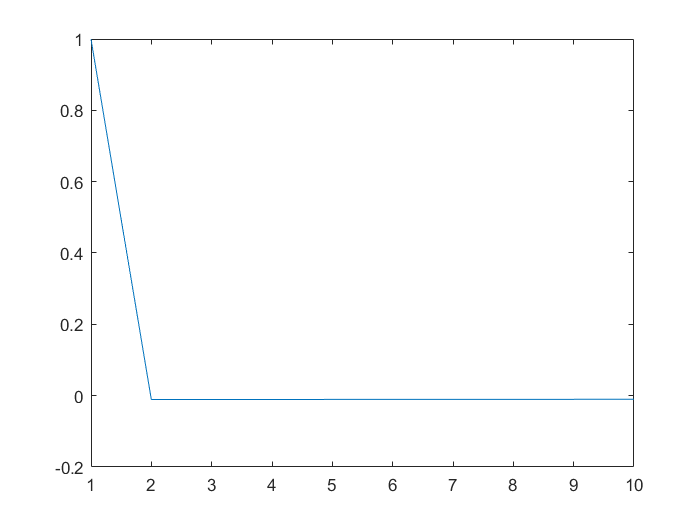


test_seq_buff = zeros(2, 2);
test_seq_out = [];
for test_i_sample = 1:size(in_audio, 1)
%     [test_seq_out(end+1, :), test_seq_buff] = f_1dFilter(fil_rlb_coef_b, fil_rlb_coef_a, in_audio(test_i_sample, :), test_seq_buff);
%     test_seq_out_now = zeros(1, 2);    
    [test_seq_out(end+1, :), test_seq_buff]  = filter(fil_rlb_coef_b, fil_rlb_coef_a, in_audio(test_i_sample, :), test_seq_buff, 1);
%     [test_seq_out(end,   2), test_seq_buff(:, 2)]  = filter(fil_rlb_coef_b, fil_rlb_coef_a, in_audio(test_i_sample, 2), test_seq_buff(:, 2));
%     test_seq_out(end+1, :) = test_seq_out_now;
end
figure;
plot(test_outFilter_mtl(:, 1))

figure;
plot(test_seq_out(:, 1))

## Functions

Define the models as functions below.

Function to calculate RMS over a set of values


$$V_{rms}[k] = \sqrt{\frac{1}{N} \sum_{n=1}^{N} v_n[k]^2}$$


function [out_rms, seq_memory] = f_findRMS(in_buffer, seq_memory)
% Stores RMS values per buffer
out_rms = zeros(0, 2);
% Goes through each symbol in frame
for i_sym = 1:length(in_buffer)
    % Obtains sequence for RMS finding
    seq_proc = [seq_memory; in_buffer(i_sym, :)];
    out_rms = [out_rms; [rms(seq_proc(:, 1)), rms(seq_proc(:, 2))]];
    seq_memory = seq_proc(2:end, :);
end
end

Function to calculate RMS - same as built-in function but faster

function out_rms_val = f_calculateRMS(in_arr)
% Calculates & returns the RMS value per formula
out_rms_val = sqrt((1/size(in_arr, 1)) * sum(in_arr .^ 2));
end

Function modelling Huovilainen's unit-delay model

function y = f_filter_linear_unit(y, in, g, k)
y(1) = y(1) + ( g * ( in - ( k * y(4) ) - y(1) ) );
y(2) = y(2) + ( g * ( y(1) - y(2) ) );
y(3) = y(3) + ( g * ( y(2) - y(3) ) );
y(4) = y(4) + ( g * ( y(3) - y(4) ) );
end

Function modelling Huovilainen's "unit-and-a-half" delay model

function [y, y_d2] = f_filter_linear_half(y, in, g, k, y_d2)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( in - ( k * ( 0.5 * ( y(4) + y_d2 ) ) ) - y(1) ) );
y(2) = y(2) + ( g * ( y(1) - y(2) ) );
y(3) = y(3) + ( g * ( y(2) - y(3) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( y(3) - y(4) ) );
end

Function modelling Huovilainen's non-linear model

function [y, y_d2] = f_filter_nonlinear(y, in, g, k, y_d2)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( tanh( in - ( k * ( 0.5 * ( y(4) + y_d2 ) ) ) ) - tanh( y(1) ) ) );
y(2) = y(2) + ( g * ( tanh( y(1) ) - tanh( y(2) ) ) );
y(3) = y(3) + ( g * ( tanh( y(2) ) - tanh( y(3) ) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( tanh( y(3) ) - tanh( y(4) ) ) );
end

Function modelling Huovilainen's non-linear 4-tap model

function [y, y_d2, y_d3, y_d4] = f_filter_nonlinear_4tap(y, in, g, k, y_d2, y_d3, y_d4)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( tanh( in - ( k * ( 0.25 * ( y(4) + y_d2 + y_d3 + y_d4 ) ) ) ) - tanh( y(1) ) ) );
y_d4 = y(2);
y(2) = y(2) + ( g * ( tanh( y(1) ) - tanh( y(2) ) ) );
y_d3 = y(3);
y(3) = y(3) + ( g * ( tanh( y(2) ) - tanh( y(3) ) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( tanh( y(3) ) - tanh( y(4) ) ) );
end

Function modelling Huovilainen's non-linear 3-tap model

function [y, y_d2, y_d3] = f_filter_nonlinear_3tap(y, in, g, k, y_d2, y_d3)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( tanh( in - ( k * ( 1/3 * ( y(4) + y_d2 + y_d3 ) ) ) ) - tanh( y(1) ) ) );
y(2) = y(2) + ( g * ( tanh( y(1) ) - tanh( y(2) ) ) );
y_d3 = y(3);
y(3) = y(3) + ( g * ( tanh( y(2) ) - tanh( y(3) ) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( tanh( y(3) ) - tanh( y(4) ) ) );
end

Function as entry point for models

function out = f_runFilter(in, tDuration, Fs, g, k, mode)
y = zeros(1, 4);
Ts = 1/Fs; % 1/Fs == Ts: recall n=t/Ts == t*Fs
% NB: Sample index 1 starts at Ts
index_start = Ts * Fs; % Index 1
% NB: Verbosity for clarification
index_end = tDuration * Fs; % Given duration of 1s
switch mode
    case "linear_unit"
        for index = index_start:1:index_end
            y = f_filter_linear_unit(y, in(index), g, k);
            out(index) = y(4);
        end
    case "linear_half"
        y_d2 = 0; % equivalent to y_d^{n-2} per H's analysis
        % See Daly's (3.6)
        for index = index_start:1:index_end
            [y, y_d2] = f_filter_linear_half(y, in(index), g, k, y_d2);
            out(index) = y(4);
        end
    case "nonlinear"
        y_d2 = 0;
        for index = index_start:1:index_end
            [y, y_d2] = f_filter_nonlinear(y, in(index), g, k, y_d2);
            out(index) = y(4);
        end
    case "nonlinear_4tap"
        y_d2 = 0;
        y_d3 = 0;
        y_d4 = 0;
        for index = index_start:1:index_end
            [y, y_d2, y_d3, y_d4] = f_filter_nonlinear_4tap(y, in(index), g, k, y_d2, y_d3, y_d4);
            out(index) = y(4);
        end
    case "nonlinear_3tap"
        y_d2 = 0;
        y_d3 = 0;
        for index = index_start:1:index_end
            [y, y_d2, y_d3] = f_filter_nonlinear_3tap(y, in(index), g, k, y_d2, y_d3);
            out(index) = y(4);
        end
end
end

Function to calculate coefficient weight.

function coefWeight = f_coefWeight(Fc, Fs)
coefWeight = 1 - exp( (-2 * pi) * ( Fc / Fs ) );
end

Function to get frequency responses

function [magnt_out, phase_out, range_f_normalised] = f_getFrqcResp(sequence, range_f, Fs)
range_f_normalised = range_f * (2 * pi) / Fs;

[magnt_out, phase_out] = deal(abs(fft(sequence)), angle(fft(sequence)));
end

Main function to plot the frequency responses

function f_plotFrqcResp_core(magnt_out, phase_out, range_f, range_f_normalised, str_title, bool_y_useLin, bool_x_useLog)
% Assign default values
plot_y_frqc = 10 * log( magnt_out(range_f, :) );
plot_y_phas = mod(( phase_out(range_f, :) * 180/pi ), -360);
plot_x = range_f_normalised / pi;
label_x = "Normalised frequency (\pi rads/second)";
label_y_frqc = "Magnitude (dB)";

switch nargin
case 6
    if bool_x_useLog
        plot_x = range_f;
        label_x = "Frequency (Hz)";
    end
    if bool_y_useLin
        plot_y_frqc = magnt_out(range_f, :);
        label_y_frqc = "Magnitude (arb.)";
    end
case 5
    if bool_y_useLin
        plot_y_frqc = magnt_out(range_f, :);
        label_y_frqc = "Magnitude (arb.)";
    end
end

%%% Plots magnitude response
sgtitle(str_title)
subplot(2, 1, 1);

hold on;
for i_plot = 1:size(magnt_out, 2)
    plot(plot_x, plot_y_frqc(:, i_plot));
end
hold off;

switch nargin
case 6
    if bool_x_useLog
    set(gca, 'XScale', 'log')
    end
end

title("Magnitude Response"); %"Spectrum (FFT)"
ylabel(label_y_frqc);
xlabel(label_x);
grid on

%%% Plots phase response
subplot(2, 1, 2);
% plot(plot_x, plot_y_phas);

hold on;
for i_plot = 1:size(phase_out, 2)
    plot(plot_x, plot_y_phas(:, i_plot));
end
hold off;

switch nargin
case 6
    if bool_x_useLog
    set(gca, 'XScale', 'log')
    end
end

title("Phase Response");
ylabel("Phase /degrees");
xlabel(label_x);
grid on
end

Function to plot the frequency spectrum figures

function [magnt_out, phase_out] = f_plotFrqcResp(sequence, range_f, Fs, str_title, bool_y_useLin, bool_x_useLog, bool_onlyReturnVals)

[magnt_out, phase_out, range_f_normalised] = f_getFrqcResp(sequence, range_f, Fs);
% range_f_normalised = range_f * (2 * pi) / Fs;

% [magnt_out, phase_out] = deal(abs(fft(sequence)), angle(fft(sequence)));

if ~bool_onlyReturnVals
    figure;
    f_plotFrqcResp_core(magnt_out, phase_out, range_f, range_f_normalised, str_title, bool_y_useLin, bool_x_useLog)
end
end

Finds EMA of signal

% function [L_out, mem_prev_input] = f_findEma(in_audio, mem_prev_input, Fs)
% 
% end

Obtains coefficients for pre-K filter

function [fil_preK_coef_b, fil_preK_coef_a] = f_getCoef_preK(Fs_filter)
fil_preK_fc = 1681.9744510;
fil_preK_q = 0.7071752;
fil_preK_VL = 1;
fil_preK_VB = 1.2587209;
fil_preK_VH = 1.5848647;
fil_preK_Omega = tan(pi * (fil_preK_fc / Fs_filter)); % The only fs-dependent param

fil_preK_coef_a = [  (fil_preK_Omega ^ 2) + (fil_preK_Omega / fil_preK_q) + 1,  ... % Coefficient a0
                    2 * ((fil_preK_Omega^2) - 1),    ...                         % Coefficient a1
                    (fil_preK_Omega^2) - (fil_preK_Omega / fil_preK_q) + 1 ...     % Coefficient a2
                    ];
fil_preK_coef_b = [  (fil_preK_VL * fil_preK_Omega^2) + (fil_preK_VB * fil_preK_Omega / fil_preK_q) + fil_preK_VH, ... % Coefficient b0
                    2 * ((fil_preK_VL * fil_preK_Omega^2) - fil_preK_VH),  ...                                     % Coefficient b1
                    (fil_preK_VL * fil_preK_Omega^2) - (fil_preK_VB * fil_preK_Omega / fil_preK_q) + fil_preK_VH  ... % Coefficient b2
                    ];
fil_preK_coef_a0 = fil_preK_coef_a(1);
fil_preK_coef_a = fil_preK_coef_a / fil_preK_coef_a0; % Normalise coefficients to a0
fil_preK_coef_b = fil_preK_coef_b / fil_preK_coef_a0; % Normalise coefficients to a0
end

Obtains coefficients for RLB filter

function [fil_rlb_coef_b, fil_rlb_coef_a] = f_getCoef_rlb(Fs_filter)
fil_rlb_fc = 38.1354709;
fil_rlb_q = 0.5003270;
fil_rlb_VL = 0;
fil_rlb_VB = 0;
fil_rlb_VH = 1.0049949;
fil_rlb_Omega = tan(pi * (fil_rlb_fc / Fs_filter)); % The only fs-dependent param

fil_rlb_coef_a = [  (fil_rlb_Omega ^ 2) + (fil_rlb_Omega / fil_rlb_q) + 1,  ... % Coefficient a0
                    2 * ((fil_rlb_Omega^2) - 1),    ...                         % Coefficient a1
                    (fil_rlb_Omega^2) - (fil_rlb_Omega / fil_rlb_q) + 1 ...     % Coefficient a2
                    ];
fil_rlb_coef_b = [  (fil_rlb_VL * fil_rlb_Omega^2) + (fil_rlb_VB * fil_rlb_Omega / fil_rlb_q) + fil_rlb_VH, ... % Coefficient b0
                    2 * ((fil_rlb_VL * fil_rlb_Omega^2) - fil_rlb_VH),  ...                                     % Coefficient b1
                    (fil_rlb_VL * fil_rlb_Omega^2) - (fil_rlb_VB * fil_rlb_Omega / fil_rlb_q) + fil_rlb_VH  ... % Coefficient b2
                    ];
fil_rlb_coef_a0 = fil_rlb_coef_a(1);
fil_rlb_coef_b = fil_rlb_coef_b / fil_rlb_coef_a0; % Normalise coefficients to a0
fil_rlb_coef_a = fil_rlb_coef_a / fil_rlb_coef_a0; % Normalise coefficients to a0
end

Function implementing the difference equations of 1D filters

function [t_out_seq_filt, t_seq_buff] = f_1dFilter(t_b, t_a, t_in_audio, t_seq_buff)

t_out_seq_filt = zeros(0, 2);
for t_i_sample = 1:size(t_in_audio, 1)

% t_buff_now = t_in_audio(t_i_sample) - (t_a(2) * t_seq_buff(2)) - (t_a(3) * t_seq_buff(1));
% t_seq_buff = [t_seq_buff(2:3, :); t_in_audio(t_i_sample, :)];
% t_out_seq_filt(end+1, :) = (t_b(1) * t_seq_buff(3)) + (t_b(2) * t_seq_buff(2)) + (t_b(3) * t_seq_buff(1));

t_buff_now = t_in_audio(t_i_sample) - (t_a(2) * t_seq_buff(2, :)) - (t_a(3) * t_seq_buff(1, :));
t_out_seq_filt(end+1, :) = (t_b(1) * t_seq_buff(3, :)) + (t_b(2) * t_seq_buff(2, :)) + (t_b(3) * t_seq_buff(1, :));
t_seq_buff = [t_seq_buff(2:3, :); t_buff_now];

end

end